Входные параметры

close all;
clear variables;
tic; % замер времени

#### 1.1 Исходные данные

% параметры волны
f = 400*10^6;
c = 3*10^8;
lambda = c/f*1000; % 0.75 м %%% убрать 
% /1000/lambda % перевод мм в м + в дилнаях волн

% константы
k = 2*pi;
eta = 120*pi;
gamma = 1.781072417990;

% геометрические данные антенны
angle = 65;


#### 1.3. Расчет координат точек исходной фигуры

lambda = 1000;

x_point_1 = 0/lambda;
z_point_1 = 0/lambda;

x_point_2 = 9.3048e+03/lambda;
z_point_2 = 1.9954e+04/lambda;

x_point_3 = 1.4236e+04/lambda;
z_point_3 = 1.9954e+04/lambda;

x_point_4 = 1.4236e+04/lambda;
z_point_4 = 15534/lambda;

x_point_5 = 6992/lambda;
z_point_5 = 0/lambda;

X_point = horzcat(x_point_1, x_point_2, x_point_3, x_point_4, x_point_5);
Z_point = horzcat(z_point_1, z_point_2, z_point_3, z_point_4, z_point_5);

#### 1.3. Расчет координат точек окружностей

pc = struct('int1', {[]}, 'int2', {[]}, 'centr', {[]}, 'r', {[]});

% begin
pc(1).int1 = [155, 0]/lambda;
pc(1).int2 = [294, 634]/lambda;
pc(1).centr = [1655, 0]/lambda;
pc(1).r = 1500/lambda;

pc(2).int1 = [9170, 19665]/lambda;
pc(2).int2 = [9623, 19954]/lambda;
pc(2).centr = [9623, 19454]/lambda;
pc(2).r = 500/lambda;

pc(3).int1 = [13718, 19954]/lambda;
pc(3).int2 = [14218, 19454]/lambda;
pc(3).centr = [13718, 19454]/lambda;
pc(3).r = 500/lambda;

pc(4).int1 = [14218, 15829]/lambda;
pc(4).int2 = [14077, 15195]/lambda;
pc(4).centr = [12718, 15829]/lambda;
pc(4).r = 1500/lambda;

pc(5).int1 = [7287, 634]/lambda;
pc(5).int2 = [7147, 0]/lambda;
pc(5).centr = [8647, 0]/lambda;
pc(5).r = 1500/lambda;

Параметры окружностей

% первая окружность (1/4 окружности)
phi_1_begin = 0; % относительно оси х
phi_1_end = acosd( ...
                 (pc(1).centr(1)-pc(1).int2(1)) ...
                  /pc(1).r)

phi_1_end = 24.8606

dphi_1 = phi_1_end - phi_1_begin;

% вторая окружность 
phi_2_begin = acosd( ...
                 (pc(2).centr(1)-pc(2).int1(1)) ...
                  /pc(2).r); % относительно оси х
phi_2_end = acosd( ...
                 (pc(2).centr(1)-pc(2).int2(1)) ...
                  /pc(2).r);
dphi_2 = phi_2_end - phi_2_begin;

% третья окружность 
phi_3_begin = acosd( ...
                 (pc(3).centr(1)-pc(3).int1(1)) ...
                  /pc(3).r); % относительно оси х
phi_3_end = acosd( ...
                 (pc(3).centr(1)-pc(3).int2(1)) ...
                  /pc(3).r);
dphi_3 = phi_3_end - phi_3_begin;

% четверта окружность
phi_4_begin = acosd( ...
                 (pc(4).centr(1)-pc(4).int1(1)) ...
                  /pc(4).r); % относительно оси х
phi_4_end = acosd( ...
                 (pc(4).centr(1)-pc(4).int2(1)) ...
                  /pc(4).r);
dphi_4 = abs(phi_4_end - phi_4_begin);

% пятая окружность
phi_5_begin = acosd( ...
                 (pc(5).centr(1)-pc(5).int1(1)) ...
                  /pc(5).r);
phi_5_end = acosd( ...
                 (pc(5).centr(1)-pc(5).int2(1)) ...
                  /pc(5).r);
dphi_5 = abs(phi_5_end - phi_5_begin);


#### Построение окружностей

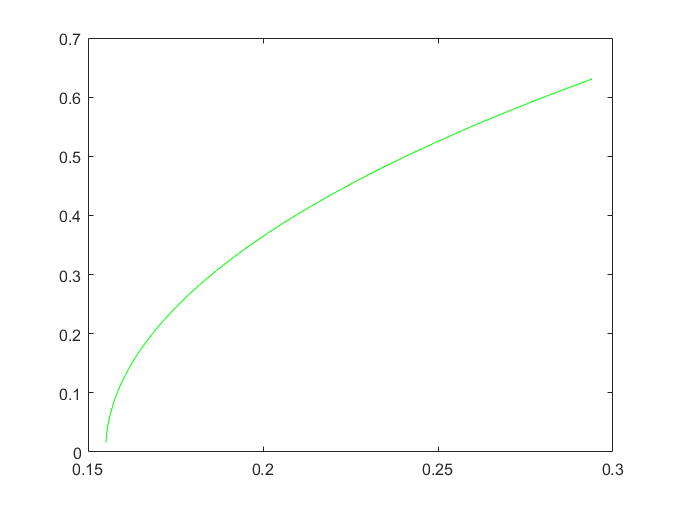

%%% Построим дугу окружности 1

N1_t = 40;
R1 = pc(1).r;
% угловой шаг окружности
for i = 1 : N1_t
    phid_step = dphi_1/N1_t;
    t1(i) = phid_step*i;
    dx1_c(i) = 2*R1*sind(dphi_1/2);
end

x1_c = pc(1).centr(1);
z1_c = pc(1).centr(2);

x1_r = R1*cosd(-t1+180) + x1_c;
z1_r = R1*sind(-t1+180) + z1_c;

figure;
plot(x1_r, z1_r,'g')

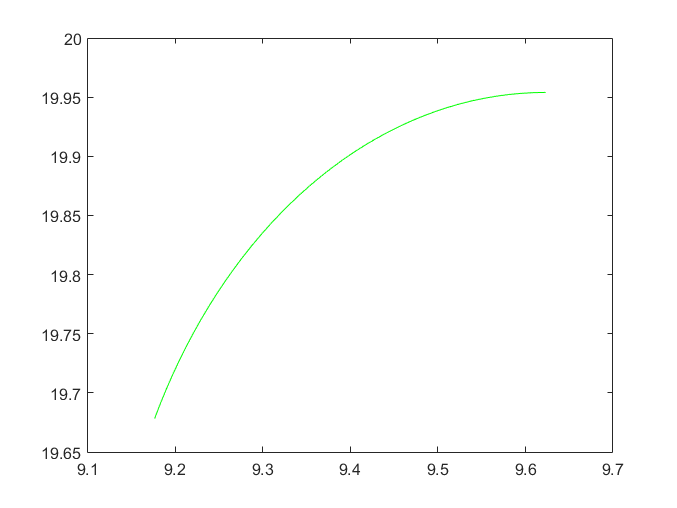

%%% Построим дугу окружности 2

N2_t = 40;
R2 = pc(2).r;
% угловой шаг окружности
for i = 1 : N2_t
    phid_step = dphi_2/N2_t;
    t2(i) = phi_2_begin + phid_step*i;
    dx2_c(i) = 2*R2*sind(dphi_2/2);
end

x2_c = pc(2).centr(1);
z2_c = pc(2).centr(2);

x2_r = R2*cosd(-t2+180) + x2_c;
z2_r = R2*sind(-t2+180) + z2_c;

figure;
plot(x2_r, z2_r,'g')

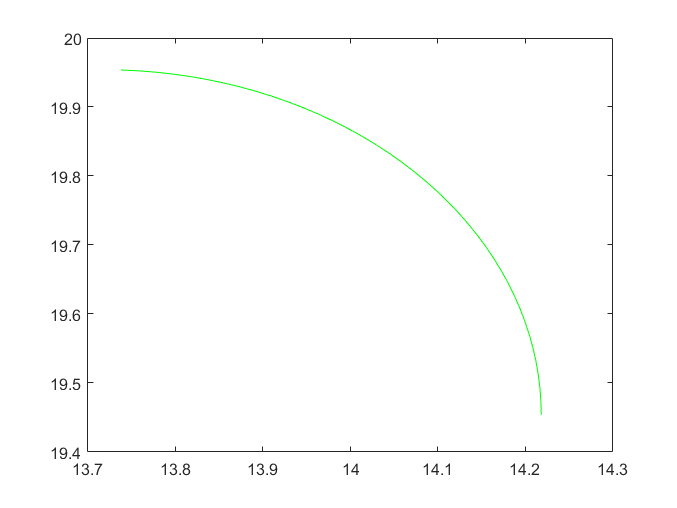

%%% Построим дугу окружности 3

N3_t = 40;
R3 = pc(3).r;
% угловой шаг окружности
for i = 1 : N3_t
    phid_step = dphi_3/N3_t;
    t3(i) = phi_3_begin + phid_step*i;
    dx3_c(i) = 2*R3*sind(dphi_3/2);
end

x3_c = pc(3).centr(1);
z3_c = pc(3).centr(2);

x3_r = R3*cosd(-t3+180) + x3_c;
z3_r = R3*sind(-t3+180) + z3_c;

figure;
plot(x3_r, z3_r,'g')

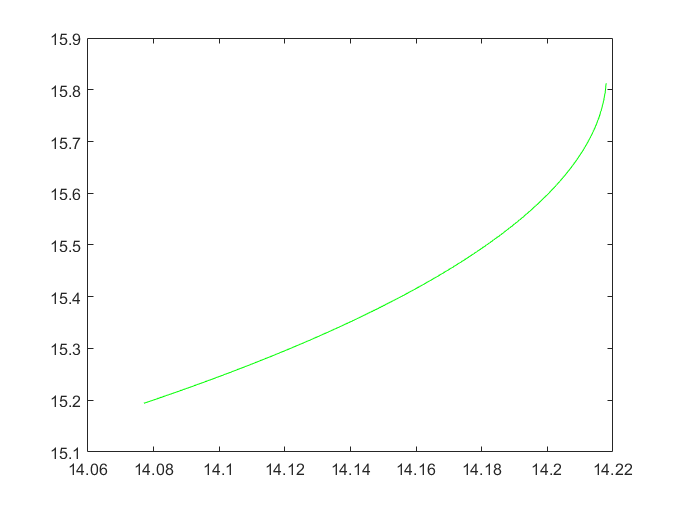

%%% Построим дугу окружности 4

N4_t = 40;
R4 = pc(4).r;
% угловой шаг окружности
for i = 1 : N4_t
    phid_step = dphi_4/N4_t;
    t4(i) =  phid_step*i;
    dx4_c(i) = 2*R4*sind(dphi_4/2);
end

x4_c = pc(4).centr(1);
z4_c = pc(4).centr(2);

x4_r = R4*cosd(-t4) + x4_c;
z4_r = R4*sind(-t4) + z4_c;

figure;
plot(x4_r, z4_r,'g')

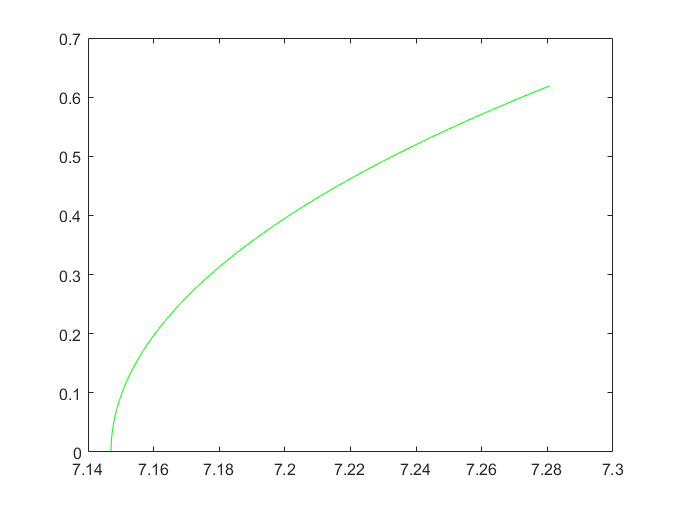

%%% Построим дугу окружности 4

N5_t = 40;
R5 = pc(5).r;
% угловой шаг окружности
for i = 1 : N5_t
    phid_step = dphi_5/N5_t;
    t5(i) = 90 + 65 + phid_step*i;
    dx5_c(i) = 2*R5*sind(dphi_5/2);
end

x5_c = pc(5).centr(1);
z5_c = pc(5).centr(2);

x5_r = R5*cosd(t5) + x5_c;
z5_r = R5*sind(t5) + z5_c;

figure;
plot(x5_r, z5_r,'g')

% Порядок точек
x1 = pc(1).int1(1);
x2 = pc(1).int2(1);
x3 = pc(2).int1(1);
x4 = pc(2).int2(1);
x5 = pc(3).int1(1);
x6 = pc(3).int2(1); 
x7 = pc(4).int1(1); 
x8 = pc(4).int2(1);
x9 = pc(5).int1(1); 
x10 = pc(5).int2(1);

z1 = pc(1).int1(2);
z2 = pc(1).int2(2);
z3 = pc(2).int1(2);
z4 = pc(2).int2(2);
z5 = pc(3).int1(2);
z6 = pc(3).int2(2); 
z7 = pc(4).int1(2); 
z8 = pc(4).int2(2);
z9 = pc(5).int1(2); 
z10 = pc(5).int2(2);


x_temp = [x1,x2,x3,x4,x5,x6,x7,x8,x9,x10];
z_temp = [z1,z2,z3,z4,z5,z6,z7,z8,z9,z10]

z_temp =          0    0.6340   19.6650   19.9540   19.9540   19.4540   15.8290   15.1950    0.6340         0


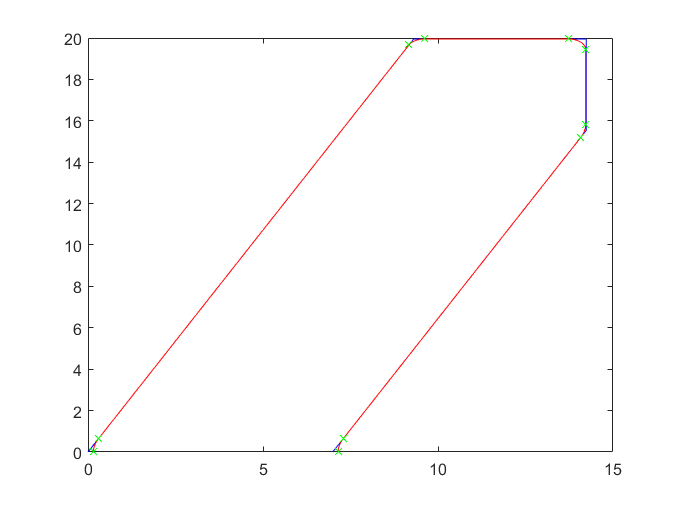

X_r = [x1_r, x2_r, x3_r, x4_r, x5_r];
Z_r = [z1_r, z2_r, z3_r, z4_r, z5_r];
hold on
plot(X_point, Z_point, 'b')
plot(X_r, Z_r, 'r')
plot(x_temp,z_temp, 'gx')
hold off

#### 1.4. Количество точек на антенне

% длины отрезков каждого участков
l12 = sqrt((x2 - x3)^2 + (z2 - z3)^2); 
l23 = sqrt((x4 - x5)^2 + (z4 - z5)^2);
l34 = sqrt((x6 - x7)^2 + (z6 - z7)^2);
l45 = sqrt((x8 - x9)^2 + (z8 - z9)^2);

% точки на окружностях
% N1_t, N2_t, N3_t, N4_t, N5_t

% точки на прямых
N12 = 50;
N23 = N12;
N34 = N12;
N45 = N12;

% cуммареное количество точек на антенне
N = 2*(N12 + N23 + N34 + N45) + 5*N1_t;

#### 2.1 Антена над землей

%% УЧАСТОК_1 - наклонный участок
dx_12 = l12/N12;

% заполнение масивов
for i = 1 : N12
    step12 = dx_12*i;
    x12(i) = x2 + cosd(angle)*step12;
    z12(i) = z2 + sind(angle)*step12;
    dx12(i) = dx_12;
end
% график
% plot(x1, z1)

%% УЧАСТОК 2 - горизонтальный участок
dx_23 = l23/N23;

% заполнение масивов
for i = 1 : N23
    step23 = dx_23*i;
    x23(i) = x4 + step23;
    z23(i) = z4;
    dx23(i) = dx_23;
end

% график
% plot(x2, z2)

%% УЧАСТОК 3 - вниз
dx_34 = l34/N34;

for i = 1 : N34
    step34 = dx_34*i;
    x34(i) = x6;
    z34(i) = z6 - step34;
    dx34(i) = dx_34;
end
% график
% plot(x3, z3);

%% УЧАСТОК 4 - наклон вниз
dx_45 = l45/N45;

for i = 1 : N45 
    step45 = dx_45*i;
    x45(i) = x8 - step45*cosd(angle);
    z45(i) = z8 - step45*sind(angle);
    dx34(i) = dx_45;
end
% график
% plot(x4, z4);

% cклеим все вместе 
X = horzcat(x12,x23,x34,x45);
Z = horzcat(z12,z23,z34,z45)

Z =     1.0146    1.3953    1.7759    2.1565    2.5372    2.9178    3.2984    3.6791    4.0597    4.4403    4.8210    5.2016    5.5822    5.9629    6.3435    6.7241    7.1048    7.4854    7.8660    8.2467    8.6273    9.0079    9.3886    9.7692   10.1498   10.5305   10.9111   11.2917   11.6724   12.0530   12.4336   12.8143   13.1949   13.5755   13.9562   14.3368   14.7174   15.0981   15.4787   15.8593   16.2400   16.6206   17.0012   17.3819   17.7625   18.1431   18.5238   18.9044   19.2850   19.6657


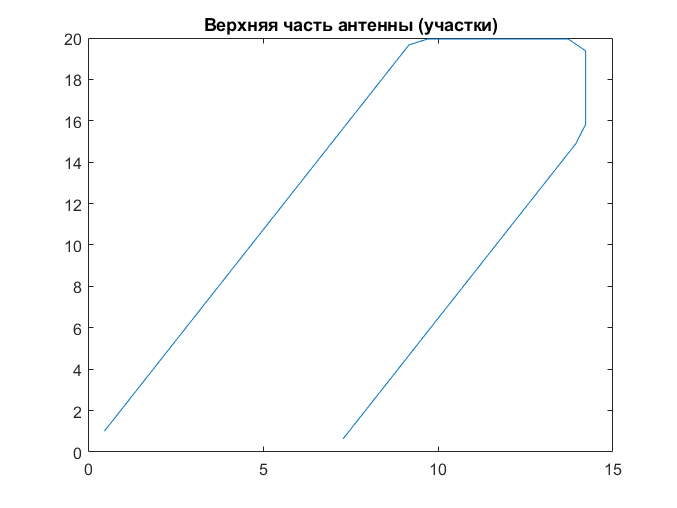


figure;
plot(X,Z)
title("Верхняя часть антенны (участки)")

#### 2.2 Вся антена (границы участков)

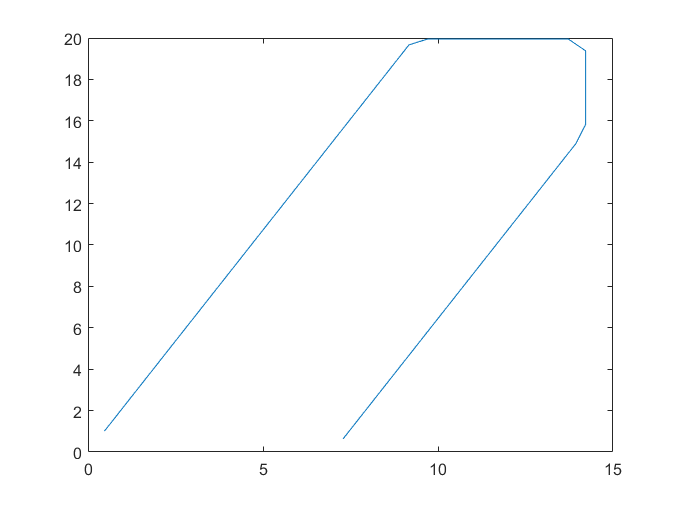

% АНТЕННА ПОД ЗЕМЛЕЙ границы участков

plot(X,Z)